# Import data from spreadsheet

Script for importing data from the following spreadsheet:

Auto-generated by MATLAB on 04-May-2021 22:49:37

## Set up the Import Options and import the data

opts = spreadsheetImportOptions("NumVariables", 3);

% Specify sheet and range
opts.Sheet = "exp_1";
opts.DataRange = "A2:C37";

% Specify column names and types
opts.VariableNames = ["f", "L", "start"];
opts.VariableTypes = ["double", "double", "double"];

% Import the data
data1 = readtable("C:\физика\2.1.3\data.xlsx", opts, "UseExcel", false)

data1 = 36×3 table
      f        L     start
    ______    ___    _____

     719.1     46      1  
       719     47     -1  
    1398.3     25      1  
      1398    146      0  
    1397.8    150     -1  
    1397.7     22      0  
    2096.3     40      1  
    2095.7    123      0  
    2095.5    205      0  
    2095.1    206     -1  
      2095    122      0  
    2094.8     41      0  
    2794.4     48      1  
    2793.8    109      0  
    2793.5    171      0  
    2793.2    171     -1  


## Clear temporary variables

clear opts

coeff_1 =   124.5000 -126.0000


xi =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


coeff_2 =    82.5000  -82.1667


xi =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


coeff_3 =    61.7500  -62.1667


xi =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


coeff_4 =    49.5500  -48.7500


xi =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


coeff_5 =    41.2500  -40.9500


xi =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


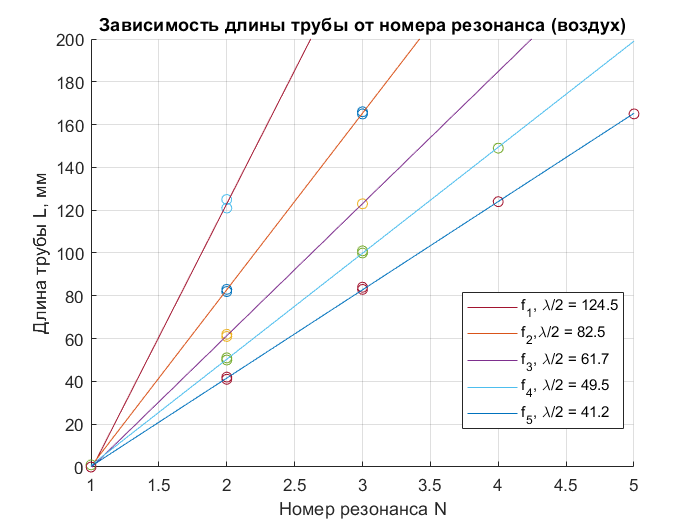

hold on;

grid on;
data = importdata("data.xlsx");
y_1 = data1.L(3:6) - data1.L(3);
y_2 = data1.L(7:12) - data1.L(7);
y_3 = data1.L(13:18) - data1.L(13);
y_4 = data1.L(19:26)- data1.L(19);
y_5 = data1.L(27:36) - data1.L(27);
x_1 = [1;2;2;1];
x_2_3 = [1;2;3;3;2;1];
x_4 = [1;2;3;4;4;3;2;1];
x_5 = [1;2;3;4;5;5;4;3;2;1];

xlim([1,5])
ylim([0,200])
point_1 = scatter(x_1,y_1);
coeff_1 = polyfit(x_1,y_1, 1)
y1 = 0;
xi = min(0):0.1:max(5)
for k=0:1
    y1 = y1 + coeff_1(1-k+1) * xi.^k;
end
gr_1 = plot(xi, y1); 

point_2 = scatter(x_2_3,y_2);
coeff_2 = polyfit(x_2_3,y_2, 1)
y1 = 0;
xi = min(0):0.1:max(5)
for k=0:1
    y1 = y1 + coeff_2(1-k+1) * xi.^k;
end
gr_2 = plot(xi, y1);

point_3 = scatter(x_2_3,y_3);
coeff_3 = polyfit(x_2_3,y_3, 1)
y1 = 0;
xi = min(0):0.1:max(5)
for k=0:1
    y1 = y1 + coeff_3(1-k+1) * xi.^k;
end
gr_3 = plot(xi, y1);

point_4 = scatter(x_4,y_4);
coeff_4 = polyfit(x_4,y_4, 1)
y1 = 0;
xi = min(0):0.1:max(5)
for k=0:1
    y1 = y1 + coeff_4(1-k+1) * xi.^k;
end
gr_4 = plot(xi, y1);

point_5 = scatter(x_5,y_5);
coeff_5 = polyfit(x_5,y_5, 1)
y1 = 0;
xi = min(0):0.1:max(5)
for k=0:1
    y1 = y1 + coeff_5(1-k+1) * xi.^k;
end
gr_5 = plot(xi, y1);

title("Зависимость длины трубы от номера резонанса (воздух)")
xlabel('Номер резонанса N')
ylabel('Длина трубы L, мм')
legend([gr_1, gr_2, gr_3, gr_4, gr_5], {'f_1, \lambda/2 = 124.5', 'f_2,\lambda/2 = 82.5', 'f_3, \lambda/2 = 61.7', 'f_4, \lambda/2 = 49.5', 'f_5, \lambda/2 = 41.2'}, 'Location','best')
hold off;
